## Question 6 -  Practitioner studies

**For all parts of the question, please provide your answers as bullet points.**

**Suppose you are a transport consultant. You are being tasked to help design a pedestrian bridge from a public railway station to a large stadium that is used for sports matches, concerts, and political rallies. This bridge will have to deal with high volumes of pedestrian traffic. There are no level changes and the length of the bridge is fixed. Figure1 below gives an indication of passenger traffic at the railway station for a typical event starting at 19:00 finishing at 20:30. Your customer is concerned with safety, construction costs, and user experience in this order of importance. The authorities have provided a simple web tool based on a model for pedestrian traffic that you must use in your work. **

**You can find it here: **[**https://seis.bristol.ac.uk/~nb14397/TMMcalculation.html**](https://seis.bristol.ac.uk/~nb14397/TMMcalculation.html)

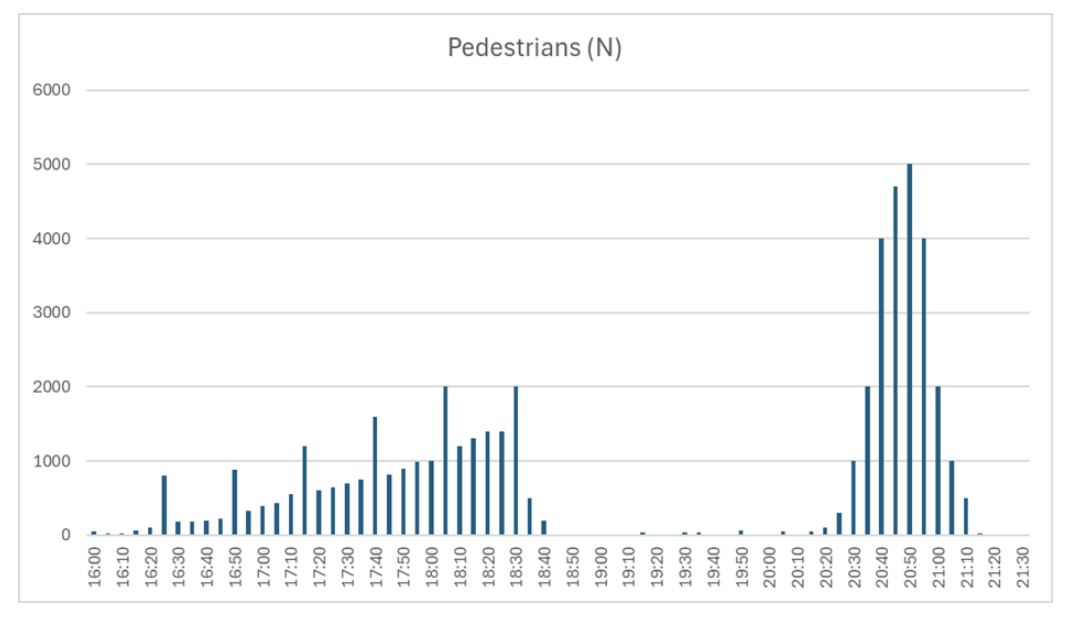

**Figure 1: Passengers numbers at the railway station (sum of arriving and departing). **

**(a) For the benefit of your customer, and for writing your report, you should understand the model in the web tool. Investigate and then describe this model, its properties, and what it predicts about pedestrian traffic by using the output the website provides, calling the website no more than 100 times (to save energetic costs and because we can imagine there may be licensing fees). In your answer, you should focus on how you use the online model output and your justification for this rather than simply stating an inferred model formulation.**

- From the model in the web tool I have obtained the values of flow when setting the number of pedestrians per square meter to 1 and varying the corridor width between the values of 1 and 10. 

- I obtained values about the flow when changing the number of pedestrians per square meter between 0.1 and 5.4 when setting the corridor width to 1 to directly compare with the values of flow when changing the corridor width.

- I did this to explore the relationships between the variables of this model and their impacts when changed. The values obtained are plotted below and fitted as seemingly required.

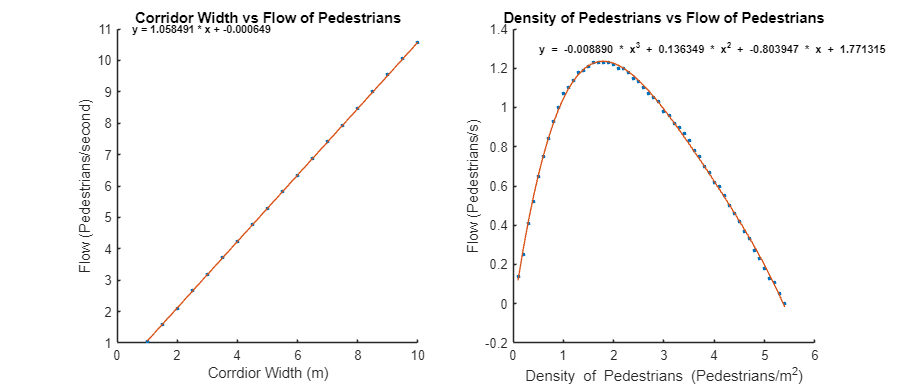

% Values plugged into the web model when changing the corridor width
CorrdiorWidthsChangingWidth = [1,1.5,2,2.5,3,3.5,4,4.5,5,5.5,6,6.5,7,7.5,8,8.5,9,9.5,10];
CorrdiorPedsPerSqMChangingWidth = 1;
% Output pedestrian flow values
CorrdiorFlowsChangingWidth = [1.05,1.59,2.11,2.66,3.17,3.71,4.23,4.78,5.29,5.82,6.33,6.88...
    ,7.41,7.92,8.48,9,9.54,10.05,10.58];
% Fitting a polynomial (here degree 1) to the data
CoeffsChangingWidth = polyfit(CorrdiorWidthsChangingWidth,CorrdiorFlowsChangingWidth,1);
% Obtaining the y-values when fitting the polynomial to the data
PolyYChangingWidth = polyval(CoeffsChangingWidth,CorrdiorWidthsChangingWidth);

% Values plugged into the web model when changing the density of
% pedestrians
CorridorWidthsChangingPedsPerSqM = 1;
CorrdiorPedsPerSqMChangingPedsPerSqM = [0.1,0.2,0.3,0.4,0.5,0.6,0.7,0.8,0.9,1,1.1,1.2,1.3,1.4,1.5,1.6...
    ,1.7,1.8,1.9,2,2.1,2.2,2.3,2.4,2.5,2.6,2.7,2.8,2.9,3,3.1,3.2,3.3,3.4,3.5,3.6,3.7,3.8,3.9,4,4.1,4.2...
    ,4.3,4.4,4.5,4.6,4.7,4.8,4.9,5,5.1,5.2,5.3,5.4];
% Output pedestrian flow values
CorridorFlowsChangingPedsPerSqM = [0.14,0.25,0.41,0.52,0.65,0.75,0.84,0.93,1,1.07,1.1,1.14,1.18,1.19...
    ,1.21,1.23,1.23,1.23,1.23,1.22,1.2,1.2,1.18,1.15,1.13,1.1,1.07,1.05,1.03,0.98,0.96,0.92,0.9,0.87...
    ,0.83,0.78,0.75,0.7,0.67,0.62,0.6,0.55,0.5,0.46,0.42,0.37,0.33,0.27,0.23,0.18,0.13,0.11,0.05,0];
% Fitting a polynomial (here degree 3) to the data
CoeffsChangingPedsPerSqM = polyfit(CorrdiorPedsPerSqMChangingPedsPerSqM,CorridorFlowsChangingPedsPerSqM,4);
% Obtaining the y-values when fitting the polynomial to the data
PolyYChangingPedsPerSqM = polyval(CoeffsChangingPedsPerSqM,CorrdiorPedsPerSqMChangingPedsPerSqM);

% Setting up the figure
figure;
sz = 8;

% Plotting when the corridor width is changing
subplot(1,2,1)
hold on
% Corridor width on the x-axis, pedestrians flow on the y-axis
scatter(CorrdiorWidthsChangingWidth,CorrdiorFlowsChangingWidth,sz,'filled')
% Plotting the fitted data for testing
plot(CorrdiorWidthsChangingWidth,PolyYChangingWidth)
hold off
% Making the plot pretty
title("Corridor Width vs Flow of Pedestrians")
xlabel("Corrdior Width (m)")
ylabel("Flow (Pedestrians/second)")
caption = sprintf('y = %f * x + %f', CoeffsChangingWidth(1), CoeffsChangingWidth(2));
text(0.5, 11, caption, 'FontSize', 8, 'Color', 'k', 'FontWeight', 'bold');

% Plotting when the pedestrian density is changing
subplot(1,2,2)
hold on
% Pedestrian density on the x-axis, pedestrians flow on the y-axis
scatter(CorrdiorPedsPerSqMChangingPedsPerSqM,CorridorFlowsChangingPedsPerSqM,sz,'filled')
% Plotting the fitted data for testing
plot(CorrdiorPedsPerSqMChangingPedsPerSqM,PolyYChangingPedsPerSqM);
hold off
% Making the plot pretty
title("Density of Pedestrians vs Flow of Pedestrians")
xlabel("Density of Pedestrians (Pedestrians/m^2)")
ylabel("Flow (Pedestrians/s)")
caption = sprintf('y = %f * x^3 + %f * x^2 + %f * x + %f', CoeffsChangingPedsPerSqM(1)...
    , CoeffsChangingPedsPerSqM(2), CoeffsChangingPedsPerSqM(3), CoeffsChangingPedsPerSqM(4));
text(0.5, 1.3, caption, 'FontSize', 8, 'Color', 'k', 'FontWeight', 'bold');

% Making the plot pretty
set(gcf,'units','inches','position',[0,0,14,6])

- The left-hand plot above therefore shows a linear relationship between the corridor width with a coefficient of approximately 1.058 and minimal y-intercept. As would be expected as if there is very minimal corridor space, there would be virtually no flow.

- The right-hand plot however shows an interesting polynomial relationship. It is an approximately quadratic relationship with roots at 0 and 5.4 and maximum value of flow of 1.22, obtained at a density of approximately 1.8. 

- This suggests that pedestrian traffic flow will increase linearly with increasing corridor width but can only be maximised if pedestrians maintain a density of around 1.8 pedestrians per square meter. Any closer and the site becomes too tight to move and any further suggests a crowd that are not particularly close and so have no need to be somewhere with time pressure, unrealistic for the scenario detailed. The maintaining of a density of pedestrians between 1 and 2  pedestrians per square meter is essential in the case of this client and while, for this brief, it is understood that low volumes of pedestrian traffic are outside the scope of the brief.

**(b) Use the model provided in the web tool and the information provided in the question to make recommendations about the design of the bridge, focusing on elements relevant to foot traffic and considering the relevant stakeholders. You may suggest adapting the model, if necessary. Explain and justify your approach. **

- The web tool details the relationships between corridor width and density of pedestrians, which is essential for this client as the bridge can be modelled as a corridor of infinite length.

- The density of pedestrians is a paramount safety consideration for high volumes of pedestrian traffic.

- The information shown in the question details the pedestrian flow at different times before and after a typical event starting and finishing, showing the typical pedestrian flow that would be apparent on the bridge between the railway station and stadium. 

- Importantly it highlights the large spike after the event finishes, highlighting the flow of approximately 25,000 people in 30 minutes or a pedestrian flow of 13.9 pedestrians per second average over that time. This time period has a peak flow of 5,000 people in 5 minutes or a approximately 16.7 pedestrians per second.

- Another thing to understand is that the spikes before the event starts are approximately 25 minutes apart, suggesting that there is a train arriving and departing from the railway station every 25 minutes.

- These values are citicial to key stakeholders:

- **Pedestrians** - will provide input into accessibility, convenience, safety concerns and pedestrian flow. This includes local residents and commuters that use the station regularly as well as fans attending the events at the stadium.

- **Stadium operators** - will need to specify event schedules and capacity as well as be primarily responsible for pedestrian safety and flow. Importantly will also fund the project (probably) and so are the primary client.

- **Train operators** - will want to know the predicted passenger flow before & after events so they can plan their railway schedules, operations and staffing around events, therefore they will be able to serve the maximum number of pedestrians in the most efficient way. They could also possibly provide some funding and so are a secondary client. 

- **Bridge/master-plan designers/engineers/architects** - should comprise of a group coordinating effectively with other stakeholders to understand pedestrian flows, safety and building code regulations as well as client desires including the surrounding area. It is critical that they use pedestrian flow modelling to understand safety, structural and accessibility requirements with the understanding that crowds normally step in-phase with each other creating larger loads on the bridge than what might be anticipated (i.e. the millennium bridge scenario).

- **Construction contractors/utility providers** - ensure correct use of materials to meet local government safety and building regulations as well minimise environmental impact. Critical for construction is the scheduling of work and deliveries to site as works during large events are likely to cause large disruptions both to construction and to pedestrian flow around the stadium, meaning it is essential to complete works around large events to minimise impacts.

- **Local government** - critical to make sure the bridge is designed and built safely that adheres to local governmental compliance measures including urban development plans, environmental impact assessments and enforce building codes and regulations. They are also likely to provide some funding and are therefore a secondary client.

- Primarily pedestrian densities should be kept at approximately 2 pedestrians per m^2, and therefore at this density the corresponding value of flow is approximately 1.2 pedestrians per second. 

- However, it is understood that pedestrian density varies significantly by event, especially during large events so a realistic density of 1 pedestrians per m^2 and therefore flow of 1.07 pedestrians per second is used to effectively handle the peak flow from the stadium. 

- Using this value, to meet a peak flow of 16.7 pedestrians per second, a bridge width of 15.7 m is therefore necessary. 

- This value was validated with the web tool.

-  Although a gross overestimate for the large majority of the time the bridge is used, a width of 15.7m would ensure smooth and safe pedestrian flow after large events at the stadium. **A sketch of the initial bridge design is shown below in the 1st image.**

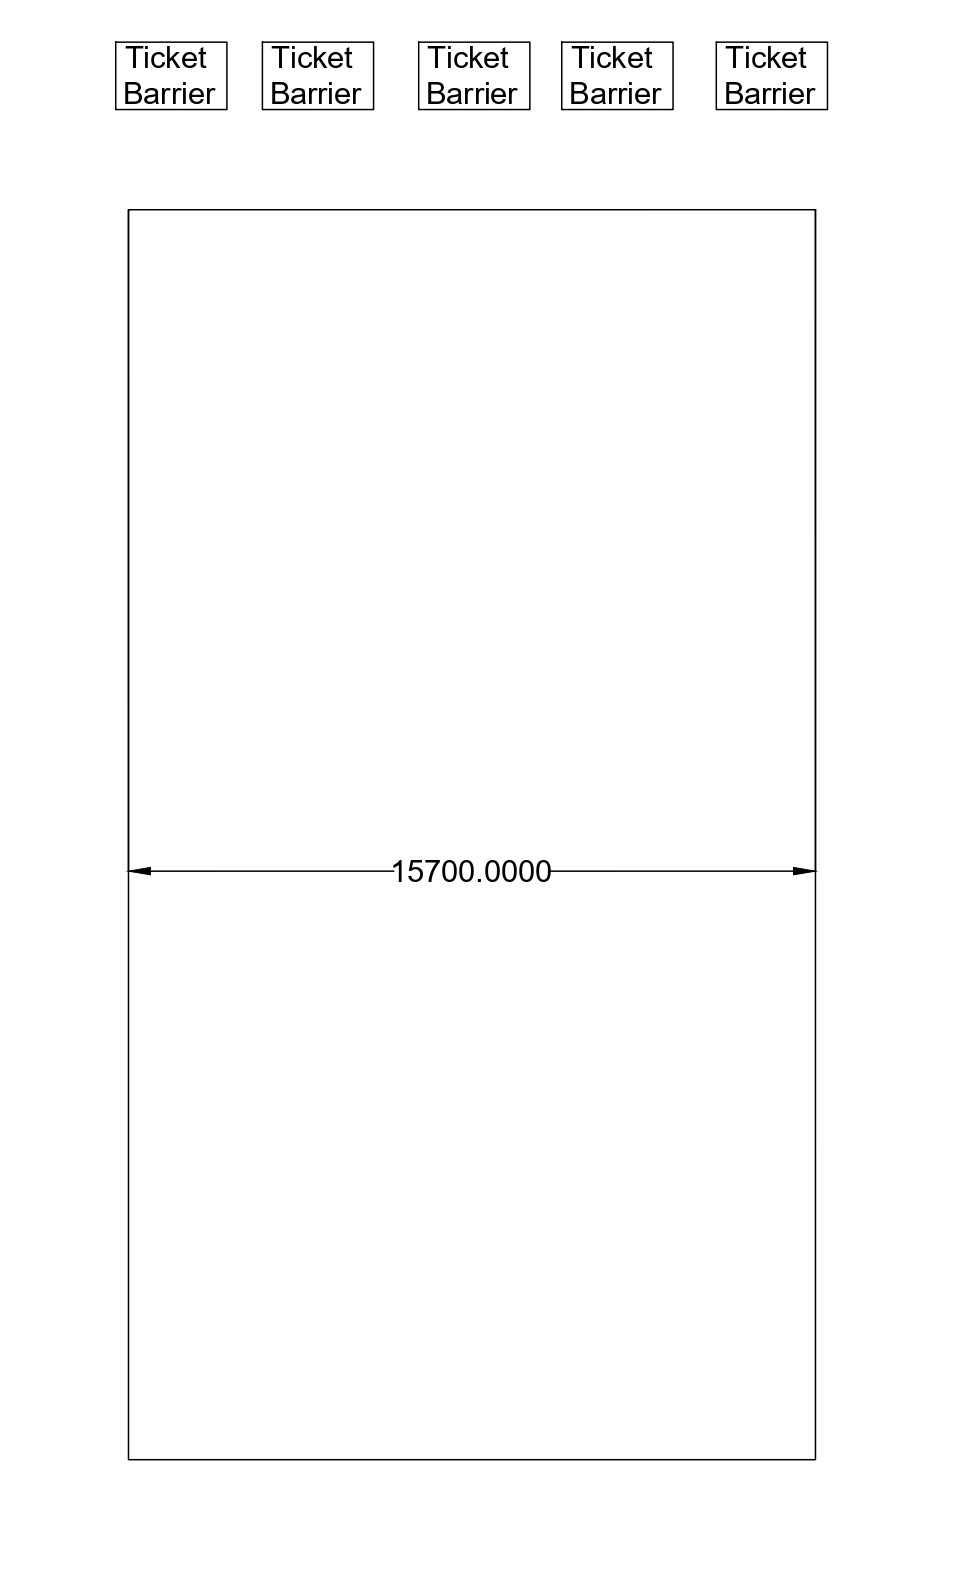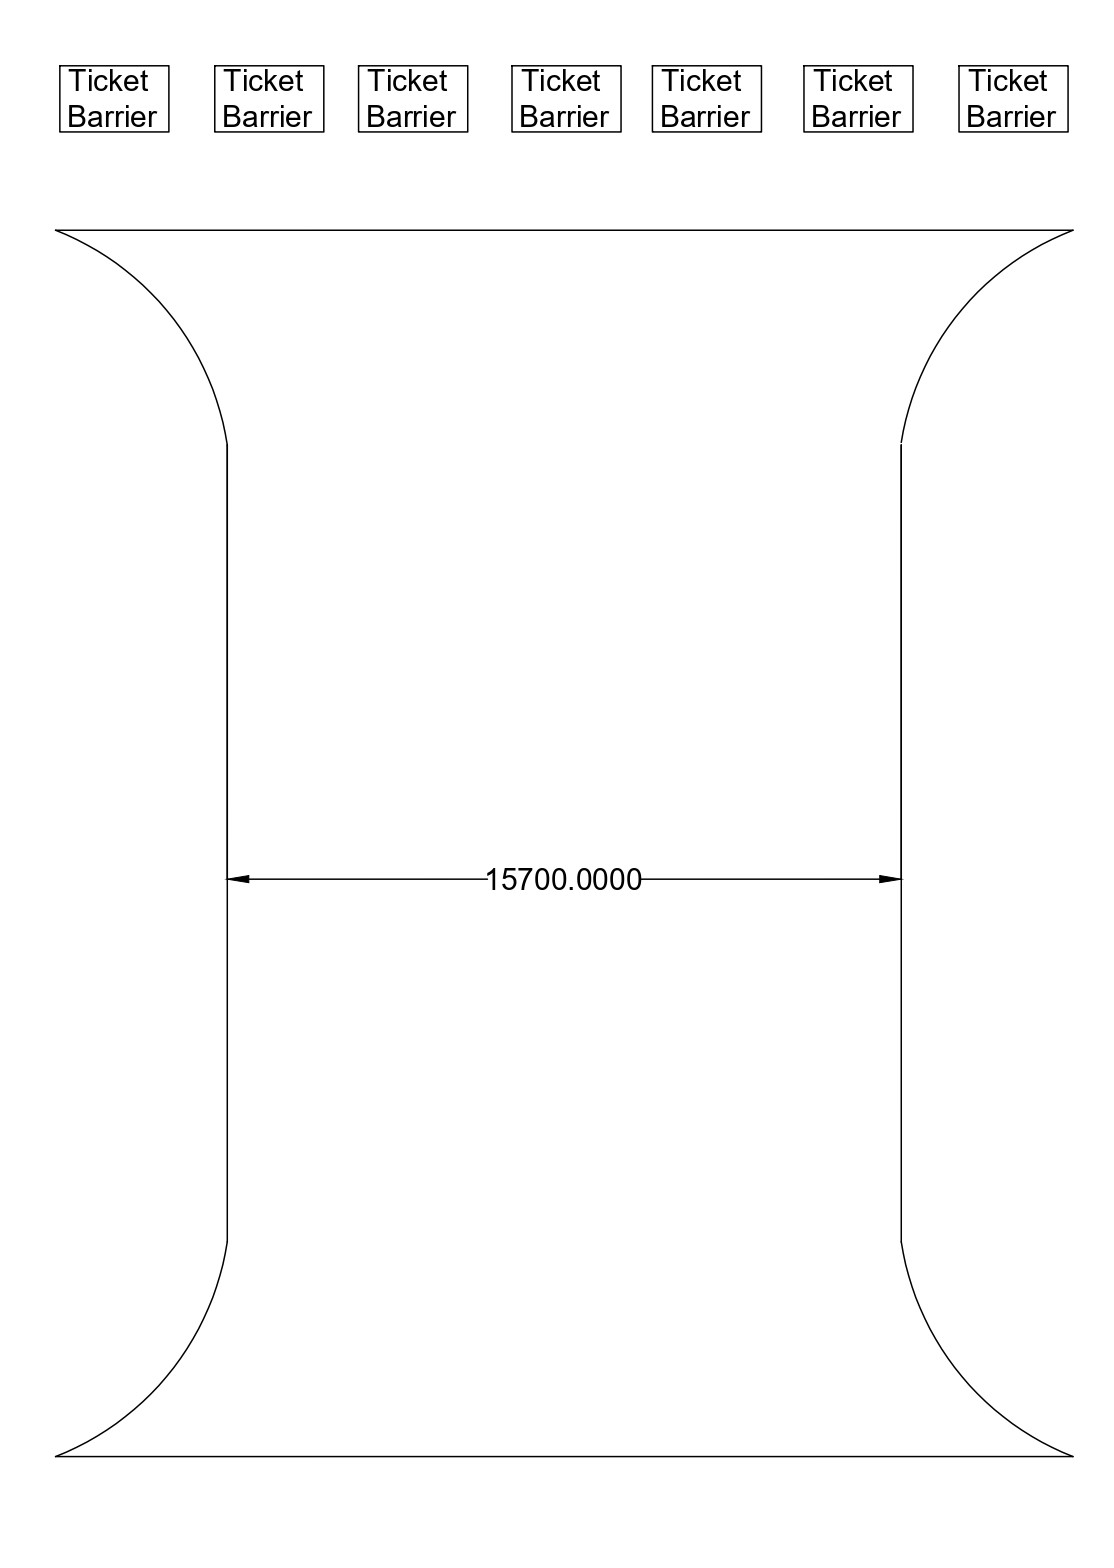

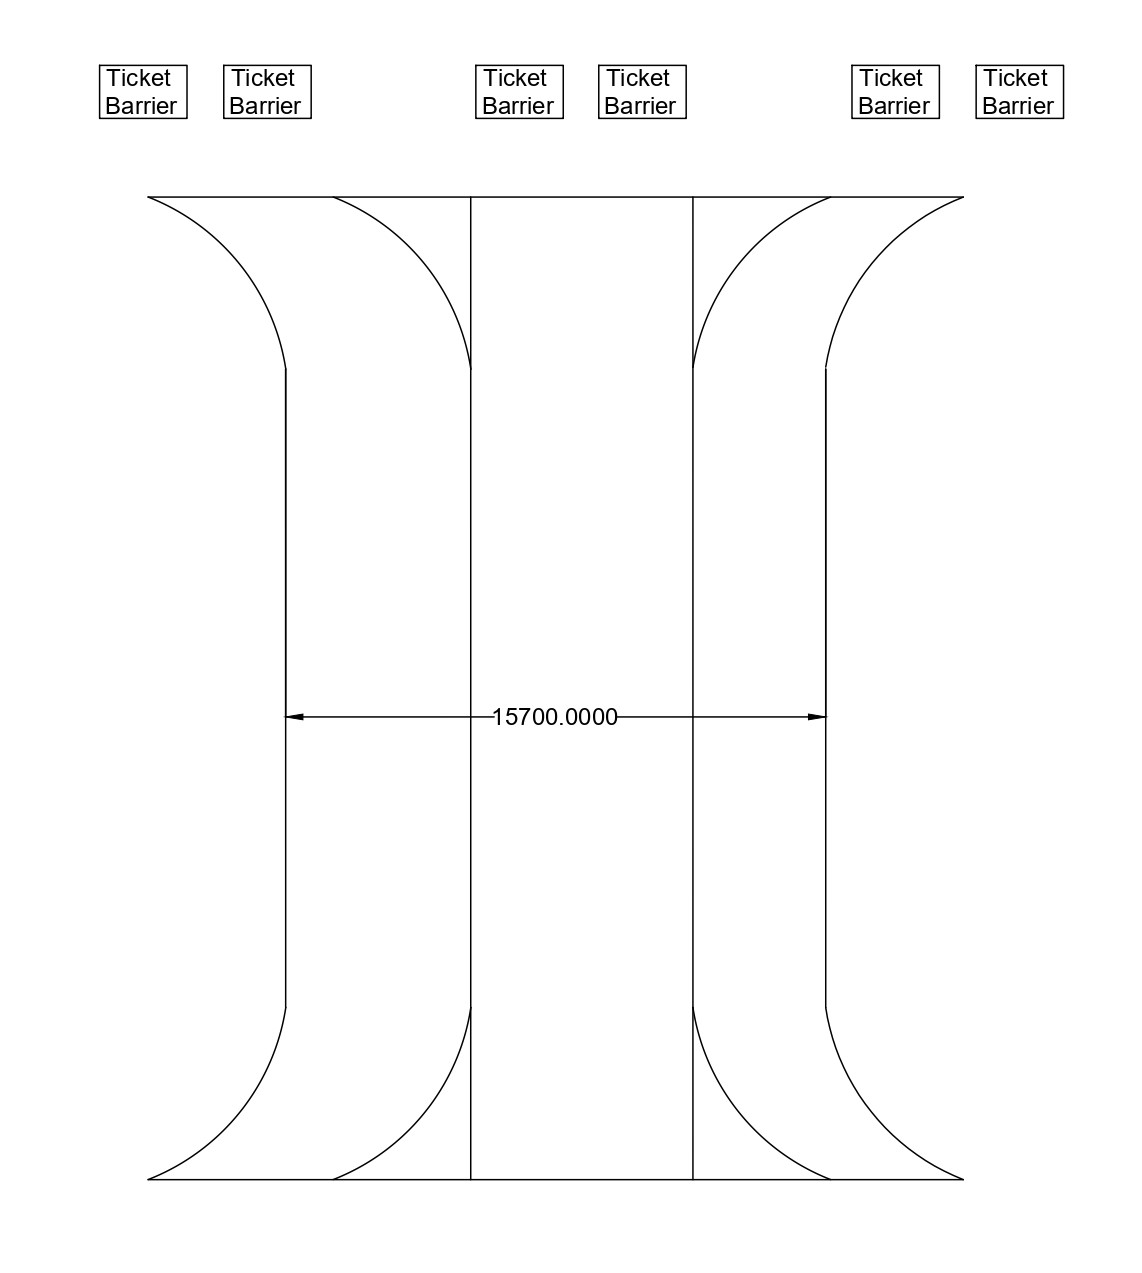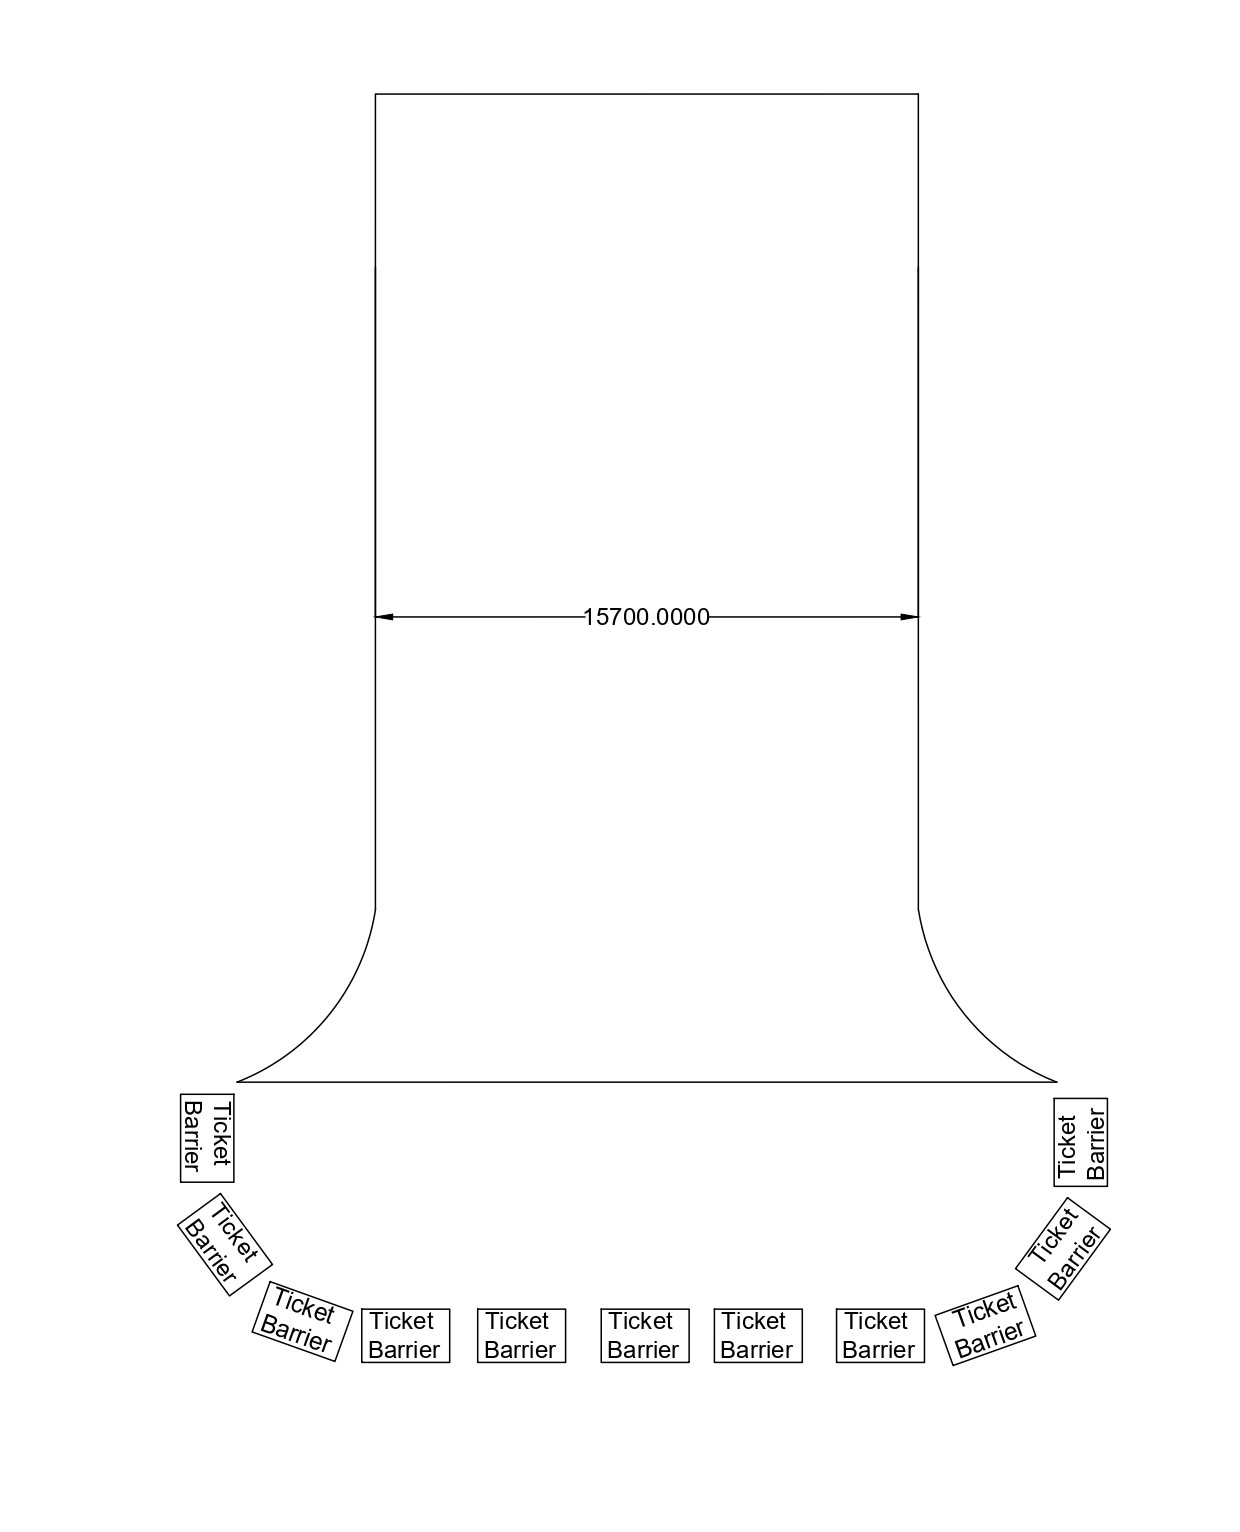

- Three suggestions for the design of the bridge are therefore made and displayed using AutoCAD:

- **Curved entrance and exits of the bridge (2nd image)** - it is expected that this will ease flow due to the removal of corners which, in all fluid models, are known to cause slight bottlenecks as it is much more difficult to turn at a right angle than to do it more gradually. By widening the end of the bridge it is also anticipated that more ticket barriers could be available for use by the crowd without the pedestrians being required to make a conscious decision to use them, aiding in preventing traffic build up. However, it is understood that this increase in passenger flow to the train station could cause issues with safety on the platform further along the path for pedestrians and the increase in people would cause extra loading on the bridge. Both issues would need to be investigated further to understand the safety implications for pedestrians but it is anticipated minimal extra materials/costs would be necessary for improved traffic flow.

- **Split the pedestrian flow up within the bridge (3rd image)** - implementation of this could aid with the loading and pedestrian flow issues mentioned for just the curved model. Pedestrians generally for streamlines in crowds and this bridge model could use that idea to its advantage with the three sections thought to follow general streamline patterns maintaining smooth flow with no pedestrian flow collisions likely to take place between streamlines. It could also help manage this flow with one section able to be blocked if ticket barriers require maintenance, there are safety concerns further along the pedestrian path or accessibility needs to be increased for those who utilise wheelchairs. However, this implementation could also be temporary for when crowd numbers are at their highest, while returning to normal curved bridge design for most of the time. This design could also cause bottlenecks with people at the entrance to the bridge but should facilitate easier crowd management.

- **Place ticket barriers at the start of the bridge in a semicircular pattern (4th image)** - This design is thought to be the best as it facilitates the easiest crowd management by the use of ticket barriers to maintain a steady flow. It also reduces the maximum loading on the bridge by meaning queueing due to high pedestrian traffic taking place before the bridge, minimising the number of people on the bridge. However, it does require extra investment in ticket barriers and therefore staff while also restricting the use of the bridge for pedestrians not using the bridge to get to the railway station as their destination. It is anticipated if this design is used, that a smaller bridge may also be available to be built, but this would come with very different planning permissions and building regulations for stakeholders to achieve.

- Adapting the web tool model to provide details of streamlines that the crowds fall into i.e. which part of the corridor will pedestrians enter into and how does their position change at the end of the corridor. This would give insights into the type of crowd flow in the corridor (i.e. if people form lines) and therefore the bridge design and ticket barrier configuration could be designed to better fit crowd flow. 

- Another item that has been identified is that at the end of the event, spikes in passenger numbers being taken away by trains can't be seen as clearly as when the pedestrians arrive at the station in the information given in the question. It can therefore not be understood the distribution of trains being used to deliver passengers back to their origins and so further crowd management techniques could be explored further if this information is available (i.e. when to allow pedestrian flow and when to not after an event).

- More granular data given in figure 1 would also be useful to understand a more detailed pedestrian flow, especially after the event to give a more accurate peak pedestrian flow value and therefore greater insight into the maximum flow experienced at the bridge with pedestrians attempting to enter the railway station.

**(c) If you were to be given access to one other model covered in the lecture slides on microscopic modelling to make your design recommendation, which model would it be, and why? Stick to the same brief as in part (b) and state clearly where in the lecture notes the model was covered. We expect a sufficiently detailed explanation as to why you choose this model including an explanation on how it would be used.**

- In this scenario there is continuous space and time and therefore a social-force model (agent based) is appropriate to model the flow of pedestrians. The Cellular-automata model is not appropriate due to it requiring discrete space while macroscopic models are inappropriate due to the crowd scenario not allowing collisions between particles and obstacles (apart from if Milwall are playing).

- A path of least effort approach to crowd simulation is recommended (PLEdestrians - Week 4: Microscopic Modelling Introduction and Concepts - Pedestrian Crowd Modelling (video 2) - slide 2). PLEdestrians is chosen due to smooth collision free motion which utilises bio-mechanical energy expended (total metabolic energy) by an agent to quantify "least effort" rather than shortest path. This is especially critical in crowds as often the shortest path determined by Dijkstra’s algorithm or similar is not the quickest nor easiest in a crowd due to this path often colliding with other pedestrian paths. Therefore a greater quantifying of self-organisation phenomena is used in PLEdestrians while still utilising the key shortest available route principle.

- The image below also details queueing of agents at a bottleneck, which the bridge is expected to be. It shows the PLEdestrian agents form a system around the doorway while still maintaining flow, typically an accurate representation of what happens at ticket barriers while the long corridor shows most agents travelling at the same speed in columns.

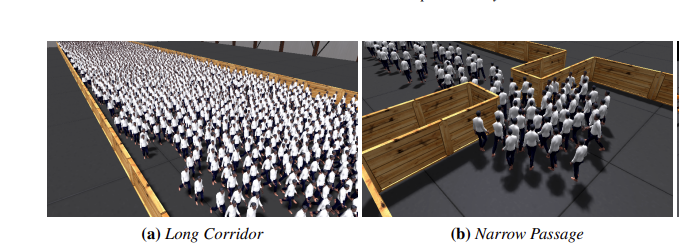

- An image of implementation of the PLEdestrains model and the comparison with a still from video footage from the Shibuya Station in Tokyo is shown below ([(PDF) PLEdestrians: A Least-Effort Approach to Crowd Simulation.](https://www.researchgate.net/publication/220789236_PLEdestrians_A_Least-Effort_Approach_to_Crowd_Simulation)). The model appears to be fairly accurate and the implementation around a train station with large crowds is particularly relevant in this scenario.

- However, it should be recognised that a combination of visual, microscopic, macroscopic and phenomenological validation models should be created to accurately predict flow from the stadium to the railway station. An example of this implemented is the modelling of Wembley Stadium ([Wembley Stadium - Pedestrian Modelling - PJA](https://pja.co.uk/project/international-stadium-pedestrians/)).